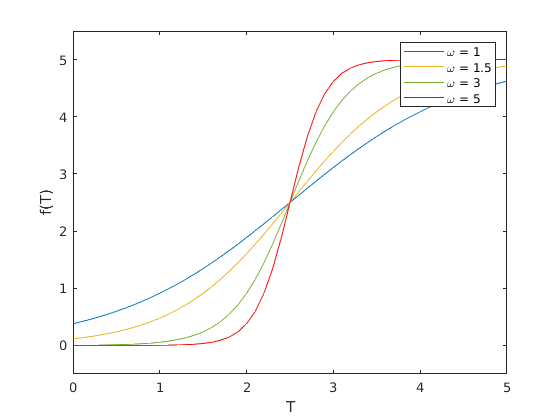

omega = [1,1.5,3,5];
f_max = 5;
T = 0:0.1:5;
T_c = 2.5;

f_T = cost_ClimateChange(T, f_max, omega(1), T_c);
plot(T, f_T, 'Color', [0,0.447,0.741])

hold on

f_T = cost_ClimateChange(T, f_max, omega(2), T_c);
plot(T, f_T, 'Color', [0.929,0.694,0.125])
f_T = cost_ClimateChange(T, f_max, omega(3), T_c);
plot(T, f_T, 'Color', [0.466,0.674,0.1880])
f_T = cost_ClimateChange(T, f_max, omega(4), T_c);
plot(T, f_T, 'Color', [1,0,0])


legend('\omega = 1', '\omega = 1.5', '\omega = 3', '\omega = 5')
xlabel('T')
ylabel('f(T)')
ylim([-0.5,5.5])

function f__ = cost_ClimateChange(T, f_max, omega, T_c)
    % Cost of climate change; page 5 of Thomas' manuscript  
    %{
    variable:
        T = temperatue from temperature projection
    parameters:
        f_max = maximum cost scaled by (c+1)
        T_c   = critical temp. at which cost is most sensitive
    %}
    f__ = (f_max)./( 1 + exp(-omega.* (T-T_c)) );
end